% Header

# Output

**Disclaimer: **Many components of the syntax and descriptions are paraphrased from MATLAB's help files. The below content is not meant to be comprehensive but rather a useful starting point. 

# fprintf

Write data (typically to the command window)

## Syntax

`fprintf(formatSpec,A1,...,An)`

## Description

`fprintf(formatSpec,A1,...,An)` formats data and displays the results on the screen.

# sprintf

Format data into character vector

## Syntax

`chr = sprintf(formatSpec,A1,...,An)`

## Description

`chr = sprintf(formatSpec,A1,...,An)` formats the data in arrays `A1,...,An` using the formatting operators specified by `formatSpec `and returns the resulting text in `chr`. The `sprintf` function formats the values in `A1,...,An` in column order. 

# Format operators 

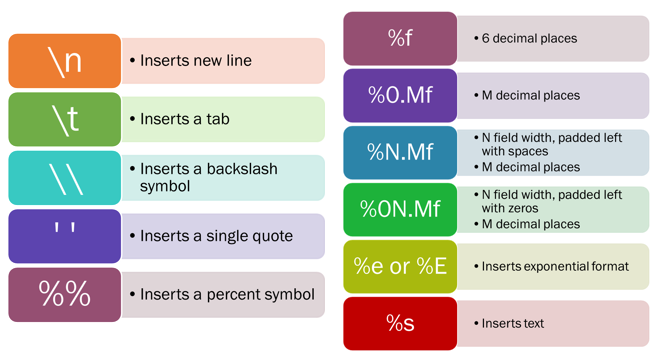

Creating variables to use with output

clear
clc
a = 6;
b = 25;
c = 0.79;
m = a/b;
n = b/c;
name = 'Fred'

name = 'Fred'

# Numeric Output

fprintf('%f',a)
fprintf('%f',n)

var_a = sprintf('%f',a)

**Student Notes:**  ####

fprintf('%f\n',n)

31.645570


**Student Notes:**  ####

fprintf('%015.3f\n',n)

00000000031.646


**Student Notes:**  ####

fprintf('%0.5f\n',n)

**Student Notes:**  ####

fprintf('%8.5f\n',n) %min of 8 characters

31.64557


fprintf('%10.5f\n',n)

  31.64557


fprintf('%12.5f\n',n) %min of 12 characters, adds 4 spaces in the front

    31.64557


fprintf('%7.5f\n',n) %field width, minimum number of total characters

31.64557


**Student Notes:**  ####

fprintf('%e\n',m)

2.400000e-01


fprintf('%0.3E\n',m)

2.400E-01


**Student Notes:**  ####

# Text and Formatting

name = input('What is the Technician''s name? ','s')
fprintf('%s\n',name)

var_name = sprintf('%s\n',name)


**Student Notes:**  ####

fprintf('%s\t\t%0.2f\n\n',name,n)

Fred		31.65



**Student Notes:**  ####

fprintf('Technician name %s\t\tValue of n %0.2f\n\n',name,n)

**Student Notes:**  ####

# Integrating sprintf with input

myText = sprintf('At $%0.2f/hour, was %s a good value?',n,name)
% must use sprintf

myRating = questdlg(myText,'Rate My Mechanic','Yes','No','Yes')

**Student Notes:**  ####

## fprintf with looping structures

x = randperm(10,6) % random permutation 

x =      5     3     6     2     9    10


fprintf('  k\t k^2\n')

  k	 k^2


fprintf('-----\t-----\n')

-----	-----


for k = 1:length(x)
    fprintf('%5.0f\t%5.0f\n', x(k), x(k)^2) %field width is five, so all aligned
end

    5	   25
    3	    9
    6	   36
    2	    4
    9	   81
   10	  100


fprintf('-----\t-----\n')

-----	-----


fprintf('%5.0f\t%5.0f\n', sum(x), sum(x.^2))

   35	  255


**Student Notes:**  ####